# Fun with the `diag` function

a = [1 2 3 4];

A = diag(a)

A =      1     0     0     0
     0     2     0     0
     0     0     3     0
     0     0     0     4


B = diag(a,-1)

B =      0     0     0     0     0
     1     0     0     0     0
     0     2     0     0     0
     0     0     3     0     0
     0     0     0     4     0


B2 = diag(a,3)

B2 =      0     0     0     1     0     0     0
     0     0     0     0     2     0     0
     0     0     0     0     0     3     0
     0     0     0     0     0     0     4
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0



M = [1 2 3; 4 5 6; 7 8 9]

M =      1     2     3
     4     5     6
     7     8     9


m = diag(M)

m =      1
     5
     9


# Eigenvalues/Eugenvectors

Given a $n\times n$ matrix $A$, we define the eigenvalue $\lambda_k$ and the eigenvector $v_k$ as a scalar and an  $n\times 1$ column vector that satisfy

${\mathrm{Av}}_k =\lambda_k v_k$.

All matrices have a total of $n$ eigenvector/eigenvalue pairs. Depending on the application, $\lambda_k$ and $v_k$ have a very specific physical meaning so knowing how to compute them is important.

N = 5;

H = hamiltonian(1,10,N);

[V,D] = eig(H)

V =     0.0000   -0.0000   -0.0000    0.0001   -0.0001    0.0025   -0.0025    0.0489    0.0489   -0.7507    0.6570
    0.0001   -0.0004   -0.0005    0.0046   -0.0046    0.0628   -0.0628    0.7026    0.7026    0.0520   -0.0455
    0.0033   -0.0109   -0.0119    0.0873   -0.0872    0.6988   -0.6988   -0.0629   -0.0629   -0.0020    0.0018
    0.0510   -0.1407   -0.1438    0.6874   -0.6848   -0.0878    0.0878    0.0033    0.0033    0.0001   -0.0001
    0.3668   -0.6929   -0.5857   -0.1409    0.1494    0.0068   -0.0069   -0.0001   -0.0001   -0.0000    0.0000
    0.8519    0.0000    0.5217   -0.0000   -0.0460    0.0000    0.0010    0.0000    0.0000    0.0000   -0.0000
    0.3668    0.6929   -0.5857    0.1409    0.1494   -0.0068   -0.0069    0.0001   -0.0001    0.0000    0.0000
    0.0510    0.1407   -0.1438   -0.6874   -0.6848    0.0878    0.0878   -0.0033    0.0033   -0.0001   -0.0001
    0.0033    0.0109   -0.0119   -0.0873   -0.0872   -0.6988   -0.6988    0.0629   -0.0629    0.0018    0.00

D =    -2.1531         0         0         0         0         0         0         0         0         0         0
         0    3.4925         0         0         0         0         0         0         0         0         0
         0         0    5.6130         0         0         0         0         0         0         0         0
         0         0         0   16.1948         0         0         0         0         0         0         0
         0         0         0         0   16.2273         0         0         0         0         0         0
         0         0         0         0         0   36.0894         0         0         0         0         0
         0         0         0         0         0         0   36.0895         0         0         0         0
         0         0         0         0         0         0         0   64.0500         0         0         0
         0         0         0         0         0         0         0         0   64.0500         0        


% First Eigenvalue/eigenvector pair
V1 = V(:,1);
D1 = D(1,1);


Check if the eigenvector/eigenvalue condition is satisfied

H*V1-D1*V1

ans = 	1.0e+-13 *

   -0.0000
   -0.0000
   -0.0017
   -0.0065
    0.1288
    0.1710
    0.0389
    0.0329
   -0.0097
   -0.0034



% Second Eigenvalue/eigenvector pair
V2 = V(:,2);
D2 = D(2,2);

H*V2-D2*V2

ans = 	1.0e+-13 *

    0.0000
   -0.0000
    0.0047
    0.0383
   -0.2354
    0.0028
    0.0266
    0.0272
   -0.0159
    0.0299


Plot the first eigenvector using a bar plot.

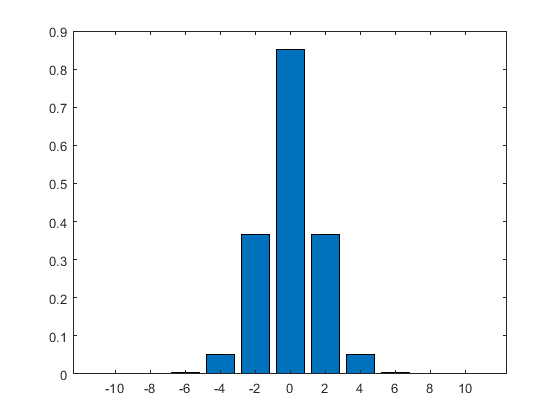

bar(-2*N:2:2*N,V1)

# Fun with Subplots

The subplot command allows you to create figures with more than one plot by defining a grid and then placing the plot in a given position(s) on the grid.

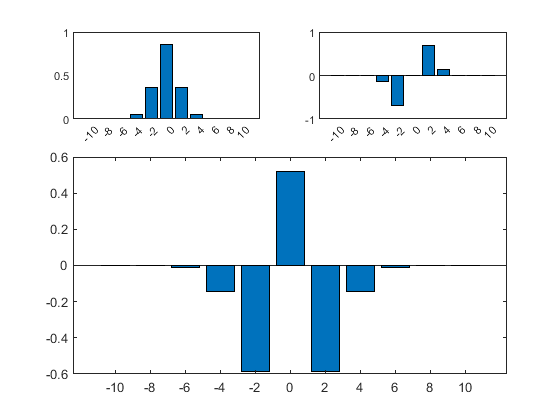

subplot(3,2,1)
bar(-2*N:2:2*N,V1)

subplot(3,2,2)
bar(-2*N:2:2*N,V2)

subplot(3,1,2:3)
bar(-2*N:2:2*N,V(:,3))

# The Hamiltonian Function

function H = hamiltonian(Er,al,N)

h = N:-1:-N;
e = ones(1,2*N);

H = 4*diag(h.^2)-al/4*diag(e,-1)-al/4*diag(e,1);
H = Er*H;

end